# NN Testing Script

We we collected our training data, we trained the NN via back-propogation, and now it is time to see how the NN performs.  When the NN is given a set a specs to meet, can it provide the proper gains to meet the specified performance?

## Starting Up and Loading Data

Load Testing Data collected from the origional GA

close all
clear all
clc

% Load Trained NN
load("neural_network.mat")

% Load Testing Data
load('GA_Data_Collection\testing_data.mat')

## Access Performance on Test Data

First, we will print out certian test cases, then look at the performance over all the test cases

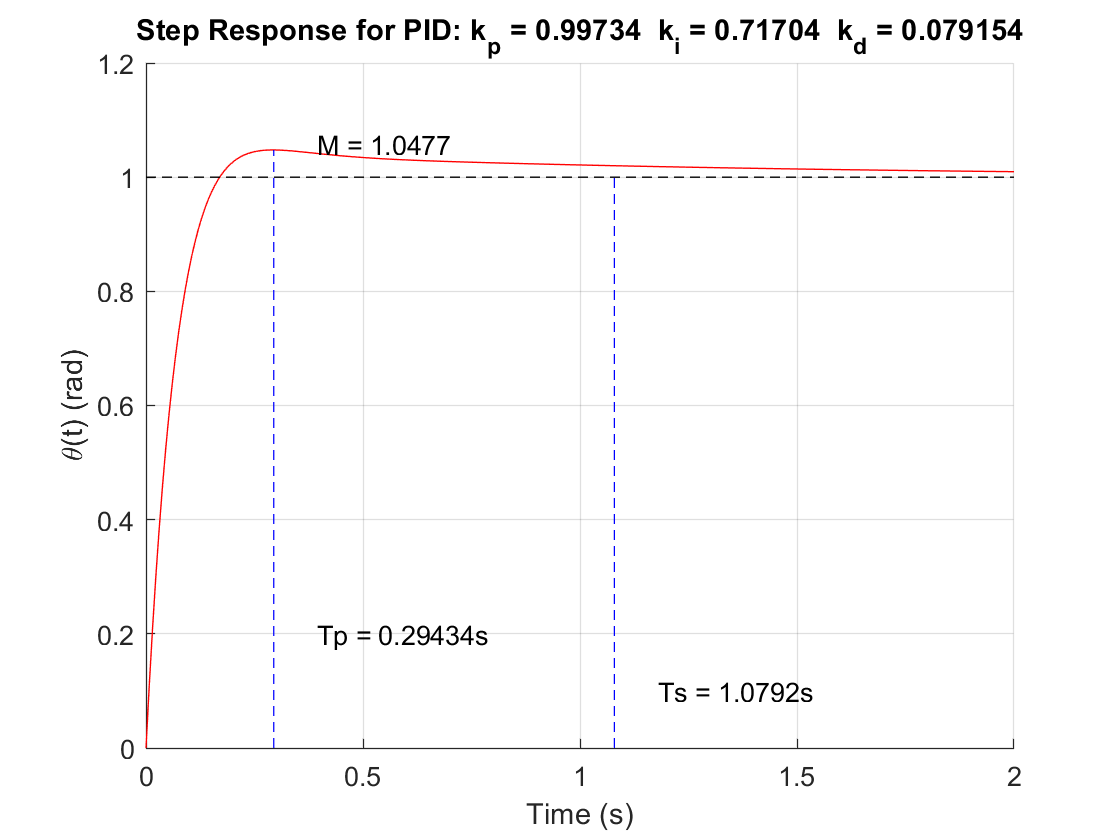

T1 = 3×3 table
                         NN Input Specs    DC Servomotor Perf.    Percent Error
                         ______________    ___________________    _____________

    Overshoot (ratio)           1                 1.0477              4.7657   
    Peak Time (s)             0.3                0.29434             -1.8868   
    Settling Time (s)         0.4                 1.0792              169.81   


T2 = 3×3 table
           GA Gains    NN Gains    Percent Error
           ________    ________    _____________

    k_p      1.0325     0.99734       -3.4054   
    k_i     0.11651     0.71704        515.41   
    k_d    0.059267    0.079154        33.554   


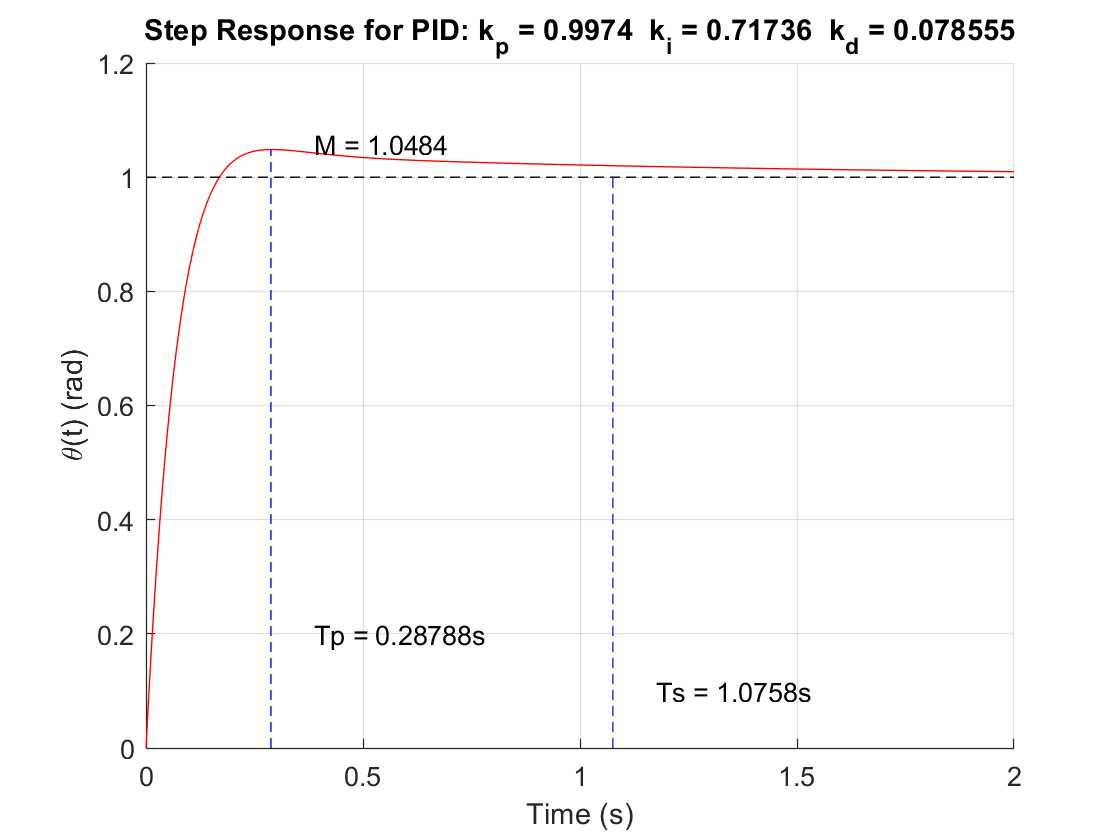

T1 = 3×3 table
                         NN Input Specs    DC Servomotor Perf.    Percent Error
                         ______________    ___________________    _____________

    Overshoot (ratio)        1.025                1.0484             2.2861    
    Peak Time (s)            0.275               0.28788             4.6832    
    Settling Time (s)         0.45                1.0758             139.06    


T2 = 3×3 table
           GA Gains    NN Gains    Percent Error
           ________    ________    _____________

    k_p      1.1286      0.9974       -11.623   
    k_i     0.45429     0.71736        57.906   
    k_d    0.078847    0.078555      -0.36962   


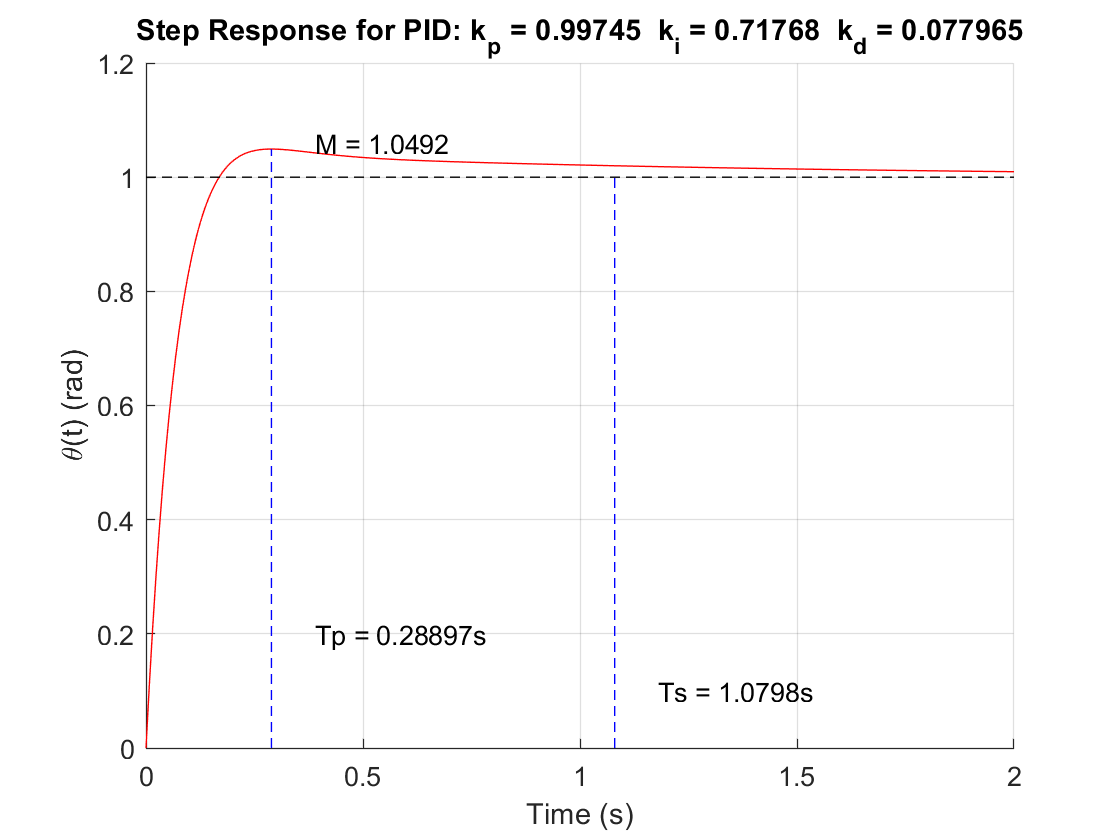

T1 = 3×3 table
                         NN Input Specs    DC Servomotor Perf.    Percent Error
                         ______________    ___________________    _____________

    Overshoot (ratio)         1.05                1.0492            -0.073806  
    Peak Time (s)             0.25               0.28897               15.589  
    Settling Time (s)          0.5                1.0798               115.97  


T2 = 3×3 table
           GA Gains    NN Gains    Percent Error
           ________    ________    _____________

    k_p      1.0971     0.99745       -9.0808   
    k_i     0.59991     0.71768        19.632   
    k_d    0.060021    0.077965        29.896   


% Define Controller
controller = "PID";

% Ten Total Test Cases
for ii = 1 : length(testing_inputs
    fitness(ii) = NN.test_NN(ii, testing_inputs, testing_outputs, controller);
end

    fitness(1) = NN.test_NN(i1, [1 0.15 2], [, controller);


    1.0000    0.3000    0.4000



## Fitness of each Test Case

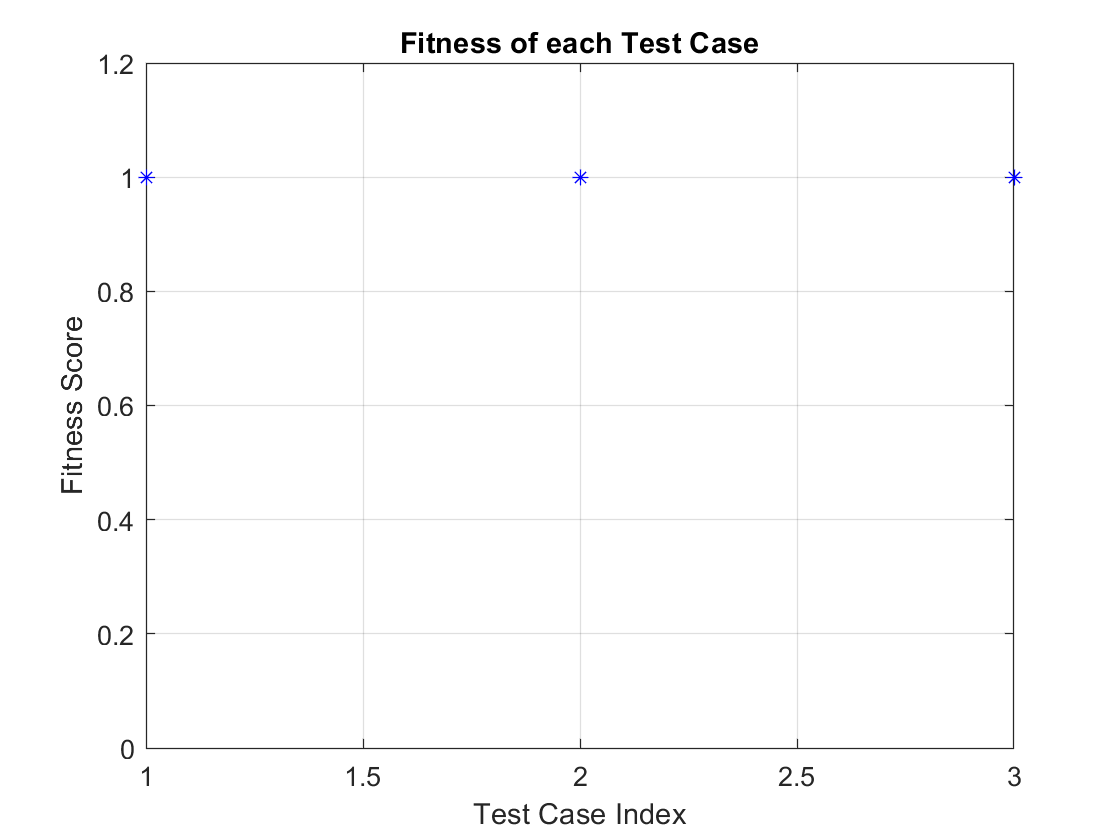

% % Indexes of Test Cases
n = 1 : length(testing_inputs);

% Plot Fitness Scores of Each Testing Case
figure
plot(n, fitness, 'b*')
title('Fitness of each Test Case')
xlabel('Test Case Index')
ylabel('Fitness Score')
ylim([0 1.2])
grid on